clc;clear;close all;
global mu 
mu = 398600.4418;       % 地球引力常数 (km^3/s^2)
Re = 6371;              % 地球平均半径 (km)
w_earth = 7.292115e-5;  % 地球自转角速度 (rad/s)
fprintf('===== 两种积分方法对比 =====\n');

===== 两种积分方法对比 =====


-------由状态向量解算出的轨道根数展示如下----------
地球引力常数 (km³/s²) = 398600

状态矢量:
位置 r (km) = [-5102 -8228 -2105]
速度 v (km/s) = [-4.348 3.478 -2.846]
角动量 (km²/s) = 61951.9
偏心率 = 0.0289885
升交点赤经 (度) = 80.0944
轨道倾角 (度) = 149.757
近地点幅角 (度) = 11.0904
真近点角 (度) = 193.86
半长轴 (km) = 9636.9


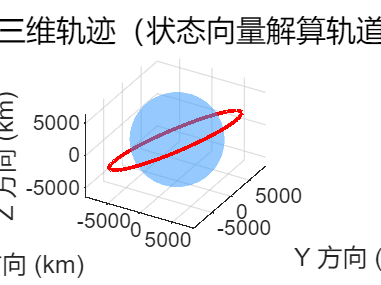

% 初始状态（基础轨道）
R0 = [-5102, -8228, -2105];  % 初始位置 (km)
V0 = [-4.348, 3.478, -2.846]; % 初始速度 (km/s)
%求解轨道根数计算周期
orbit_coe=coe_caculate(R0,V0);

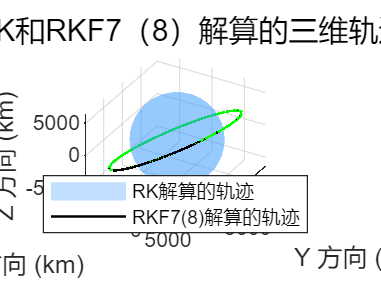

a=orbit_coe(7);
tf=2*pi*sqrt(a*a*a/mu);
h = 0.1;       % 时间步长 (s)
t0 = 0;        % 初始时间 (s)
tout = t0:h:tf;% 时间序列
N=ceil(tf/h+1);
Xout_rk4 = zeros(N,6);
%四阶龙格-库塔法（RK4）求解
R = R0; V = V0;
X = [R, V];
Xout_rk4(1,:) = X;
for k=2:N
    [k1r, k1v] = stateequation(R, V);
    [k2r, k2v] = stateequation(R + 0.5*h*k1r, V + 0.5*h*k1v);
    [k3r, k3v] = stateequation(R + 0.5*h*k2r, V + 0.5*h*k2v);
    [k4r, k4v] = stateequation(R + h*k3r, V + h*k3v);
    R = R + h*(k1r + 2*k2r + 2*k3r + k4r)/6;
    V = V + h*(k1v + 2*k2v + 2*k3v + k4v)/6;
    X = [R, V];
    Xout_rk4(k,:) = X;
end
%RKF78求解
Xout_rkf78 = zeros(N, 6);  
Xout_rkf78(1,:) = [R0, V0]; 
% RKF78系数表
alpha = [0, 2/27, 1/9, 1/6, 5/12, 1/2, 5/6, 1/6, 2/3, 1/3, 1, 0,1];  % 阶段系数
beta = [            
    0,          0,          0,          0,          0,          0,          0,          0,          0,          0,          0           0;            
    2/27,       0,          0,          0,          0,          0,          0,          0,          0,          0,          0           0;           
    1/36,       1/12,       0,          0,          0,          0,          0,          0,          0,          0,          0           0;           
    1/24,       0,          1/8,        0,          0,          0,          0,          0,          0,          0,          0           0;           
    5/12,       0,          -25/16,     25/16,      0,          0,          0,          0,          0,          0,          0           0;           
    1/20,       0,          0,          1/4,        1/5,        0,          0,          0,          0,          0,          0           0;           
    -25/108,    0,          0,          125/108,    -65/27,     125/54,     0,          0,          0,          0,          0           0;           
    31/300,     0,          0,          0,          61/225,     -2/9,       13/900,     0,          0,          0,          0           0;           
    2,          0,          0,          -53/6,     704/45,      -107/9,      67/90,      3,          0,          0,         0           0;           
    -91/108,    0,          0,          23/108,   -976/135,    311/54,    -19/60,     17/6          -1/12,        0,        0           0;           
    2383/4100,  0,          0,          -341/164,   4496/1025,   -301/82,    2133/4100,    45/82,   45/162,       18/41,    0           0;           
    3/205,      0,         0,           0,             0,      -6/41,     -3/205,      -3/41,     -3/41,        3/41,      6/41        0  
  -1777/4100    0           0          -341/164,     4496/1025   -289/82    2193/4100    51/82       33/164      12/41      0           1];  % 权重系数

% 7阶主解权重（b7）和8阶辅助解权重（b8）
b7 = [41/840, 0, 0, 0, 0, 34/105, 9/35, 9/35, 9/280, 9/280, 41/840,0];
b8 = [0, 0, 0, 0, 0, 34/105, 9/35, 9/35, 9/280, 9/280, 0, 41/840,41/840];

% RKF7(8)迭代求解
R = R0;  % 初始位置
V = V0;  % 初始速度
for k = 2:N
    % 计算12个阶段的k值（k_r为位置导数的阶段值，k_v为速度导数的阶段值）
    k_r = zeros(13, 3);  % 12个阶段×3维位置
    k_v = zeros(13, 3);  % 12个阶段×3维速度
    
    % 第1阶段（k=1）
    [k_r(1,:), k_v(1,:)] = stateequation(R, V);
    
    % 第2-12阶段（k=2~12）
    for i = 2:13
        % 累加前i-1个阶段的权重
        R_temp = R + h * sum(beta(i, 1:i-1)' .* k_r(1:i-1, :), 1);
        V_temp = V + h * sum(beta(i, 1:i-1)' .* k_v(1:i-1, :), 1);
        [k_r(i,:), k_v(i,:)] = stateequation(R_temp, V_temp);
    end
    
    % 计算7阶主解（R7, V7）和8阶辅助解（R8, V8）
    R7 = R + h * sum(b7' .* k_r(1:12, :), 1);
    V7 = V + h * sum(b7' .* k_v(1:12, :), 1);
    R8 = R + h * sum(b8' .* k_r(1:13, :), 1);
    V8 = V + h * sum(b8' .* k_v(1:13, :), 1);
    
    % 固定步长：直接采用7阶主解（若需8阶精度，可替换为R8, V8）
    R = R7;
    V = V7;
    
    % 存储结果
    Xout_rkf78(k,:) = [R, V];
end
%涵盖地球的轨迹解算
[X, Y, Z] = sphere(50);
R_earth = 6378137/1000;  % 地球赤道半径 (m)
surf(X*R_earth, Y*R_earth, Z*R_earth, 'FaceColor', [0.2, 0.6, 1], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
axis equal;
hold on;
grid on;
xlabel('X 方向 (km)','FontSize',10);
ylabel('Y 方向 (km)','FontSize',10);
zlabel('Z 方向 (km)','FontSize',10);
title('由RK和RKF7（8）解算的三维轨迹','FontSize',12);
view(30, 30);  % 调整视角（方位角30°，仰角30°）
plot3(Xout_rk4(:,1), Xout_rk4(:,2), Xout_rk4(:,3), 'k-', 'LineWidth',1, 'DisplayName','RK4法');hold on;
plot3(Xout_rkf78(:,1), Xout_rkf78(:,2), Xout_rkf78(:,3), 'g-', 'LineWidth',1, 'DisplayName','RK78法');
legend('RK解算的轨迹', 'RKF7(8)解算的轨迹',"location","best");grid on;

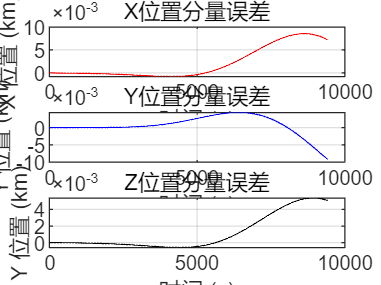

tout=[tout tout(end)];
%误差计算及其绘图
error=Xout_rk4-Xout_rkf78;
subplot(3,1,1);
plot(tout, error(:,1),'r-')
xlabel('时间 (s)'); ylabel('X 位置 (km)'); title('X位置分量误差');
grid on;

subplot(3,1,2);
plot(tout, error(:,2),'b-')
xlabel('时间 (s)'); ylabel('Y 位置 (km)'); title('Y位置分量误差');
grid on;

subplot(3,1,3);
plot(tout, error(:,3),'k-')
xlabel('时间 (s)'); ylabel('Y 位置 (km)'); title('Z位置分量误差');
grid on;